# Trabalho 6 - Realimentação de estados

## Nome: Gabrielly Barcelos Cariman

## Data limite para entrega: 13/12, 6h

**Importante lembrar:**

- Entrega após a data/horário acima: a nota será multiplicada por $1-e^{-30/h}$, onde h são as horas em atraso (Exemplo: 24h, multiplica por 0.71).

- O trabalho não é recebido por email

- Cabe a vocês garantir que o documento entregue é um arquivo pdf legível, e que não foi entregue com erro. Para isto, basta depositar e abrir para conferir.

- Código é apenas uma informação complementar, e não é considerada parte da solução para fins de avaliação.

- Caso não haja tempo de fazer todo o trabalho, entregue no prazo o que estiver pronto.

I=14;
[G,ts0,sat]=init_t6(I);

**Atividade 1) **Obtenha a realimentação de estados tal que a saída tenha sobreelevação $UP\leq 4.3\%$ e o tempo de estabelecimento  $t_s\leq ts_0$. Deve-se ajustar o ganho da FT de malha fechada de modo que a saída tenda para a referência unitária.  

Faz parte da resposta:

- Explicar como escolheu os polos de malha fechada.

- Mostrar e explicar a saída de malha aberta e a de malha fechada, o sinal de controle, a FT de malha fechada.

- Comentar o sinal de controle e seu valor em regime.

G

G =
 
              11.08
  ------------------------------
  s^3 + 17 s^2 + 74.75 s + 33.25
 
Continuous-time transfer function.
Model Properties


ts0

ts0 = 0.5758

Seja o sistema dado por:


$$\dot{x}=Ax+Bu$$



$$y=Cx$$


As matrizes foram obtidas pelo método da decomposição direta:

A = [0 1 0; 0 0 1; -33.25 -74.75 -17];
B = [0; 0; 1];
C=[11.08 0 0];
D=0;

s1=ss(A,B,C,D)

s1 =
 
  A = 
           x1      x2      x3
   x1       0       1       0
   x2       0       0       1
   x3  -33.25  -74.75     -17
 
  B = 
       u1
   x1   0
   x2   0
   x3   1
 
  C = 
          x1     x2     x3
   y1  11.08      0      0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


**Realimentação de estados**

A realimentação de estados estabiliza sistemas controláveis. Portanto, será realizada uma verificação para confirmar esse aspecto.

Wc = [B A*B A*A*B]

Wc =          0         0    1.0000
         0    1.0000  -17.0000
    1.0000  -17.0000  214.2500


posto = rank(Wc)

posto = 3

Considerando que o posto da matriz é igual à sua ordem, no caso, 3 para uma matriz 3x3, isso indica que o sistema é controlável e, portanto, a realimentação de estados pode ser aplicada.

Segue a informação sobre as definições do sistema: tempo de estabilização Ts = 0.5758 segundos e UP = 4.3%

UP=4.3;
Ts=ts0;
a=log(UP/100);
zeta=sqrt(a^2/(pi^2+a^2))

zeta = 0.7077

wn=4/(Ts*zeta)

wn = 9.8158

polos=roots([1 2*zeta*wn wn^2])

polos =   -6.9463 + 6.9354i
  -6.9463 - 6.9354i


Escolheremos as localizações para o polo P3. É fundamental que P3 seja mais rápido do que os dois polos anteriores para não afetar a resposta do sistema, mantendo assim a conformidade com as especificações.

p3 = -12

p3 = -12

polos=[polos; p3]

polos =   -6.9463 + 6.9354i
  -6.9463 - 6.9354i
 -12.0000 + 0.0000i


**Realimentação de estados:**

K=place(A,B,polos)

K = 1.0e+03 *

    1.1230    0.1883    0.0089


**Sistema em malha fechada**

s1mf=ss(A-B*K,B,C,D)

s1mf =
 
  A = 
           x1      x2      x3
   x1       0       1       0
   x2       0       0       1
   x3   -1156  -263.1  -25.89
 
  B = 
       u1
   x1   0
   x2   0
   x3   1
 
  C = 
          x1     x2     x3
   y1  11.08      0      0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


**Função de transferência de malha fechada**

g1mf=tf(s1mf)

g1mf =
 
               11.08
  --------------------------------
  s^3 + 25.89 s^2 + 263.1 s + 1156
 
Continuous-time transfer function.
Model Properties


**Simulação ao degrau em malha fechada**

Confirindo que as especificações foram atendidas.

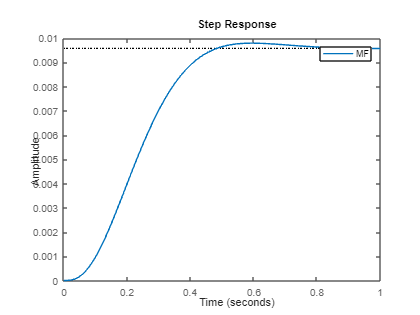

figure;step(g1mf);legend('MF')

A saída não está seguindo a referência unitária, sendo assim, é necessário aplicar um ganho multiplicativo. Este ganho será obtido ao calcular 1 dividido pelo ganho atual da saída, garantindo que o sistema alcance um valor unitário em regime.

p1 = dcgain(g1mf)

p1 = 0.0096

ganho = (1/p1)

ganho = 104.3512

g1mf = ganho*g1mf

g1mf =
 
                1156
  --------------------------------
  s^3 + 25.89 s^2 + 263.1 s + 1156
 
Continuous-time transfer function.
Model Properties


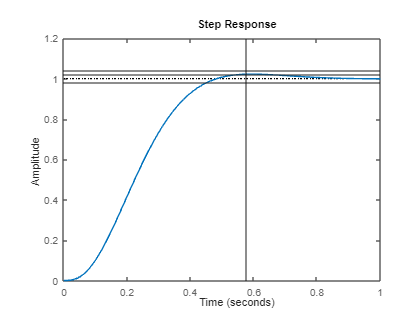

figure;step(g1mf);xline(Ts);yline(1.04);yline(0.98);yline(1.02);

A observação feita no gráfico acima revela que as especificações foram atendidas em relação ao tempo de estabelecimento, UP e referência.

**Sinal de controle:**

O sinal de controle exibe valores mais elevados inicialmente, uma vez que é o primeiro contato com o sistema, exigindo mais esforço para controlá-lo. Posteriormente, seu valor diminui gradualmente, estabilizando-se em zero. Esse comportamento é atribuído à estabilidade do sistema em um valor constante em regime, caracterizado pela ausência de erro em regime.

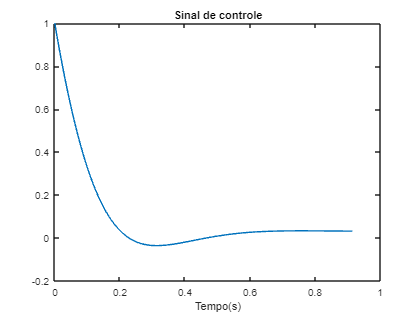

[y,t,x]=step(s1mf);
u=1-K*(x');
figure;plot(t,u);
title('Sinal de controle');
xlabel('Tempo(s)');

**Atividade 2)** Nesta atividade usa-se o controlador anterior mas o sinal de controle está limitado por uma saturação** sat.** Use a função [y,t,u] = simula_t6(s1,K,p1,sat)  para simulação com a saturação e obter os valores de y,u,t. Verifique se sob saturação a especificação é atendida. Caso não, altere a localização dos polos de malha fechada, lembrando que respostas mais rápidas exigem um sinal de controle de maior amplitude.

Na função simula_t6:

- s1 : sistema em variáveis de estado utilizado em malha aberta

- K: realimentação de estados calculada para s1

- p1: ganho multiplicado pela referência para fazer a saída tender a 1 em regime

- sat: valor máximo (em módulo) que o sinal de controle pode assumir.

Faz parte da resposta:

- Plotar a saída sem e com saturação mostrando o atendimento da especificação

- Plotar e interpretar o sinal de controle sem e com saturação

- Explicar o efeito da saturação e como foi resolvido.

s1

s1 =
 
  A = 
           x1      x2      x3
   x1       0       1       0
   x2       0       0       1
   x3  -33.25  -74.75     -17
 
  B = 
       u1
   x1   0
   x2   0
   x3   1
 
  C = 
          x1     x2     x3
   y1  11.08      0      0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


K

K = 1.0e+03 *

    1.1037    0.1855    0.0087


p1

p1 = 0.0097

sat

sat = 25

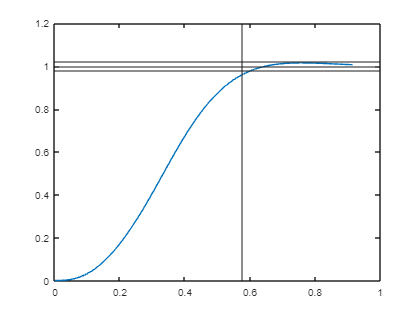

[y, t, u] = simula_t6(s1, K, p1, sat);
figure;plot(t,y);xline(Ts);yline(0.98);yline(1);yline(1.02);

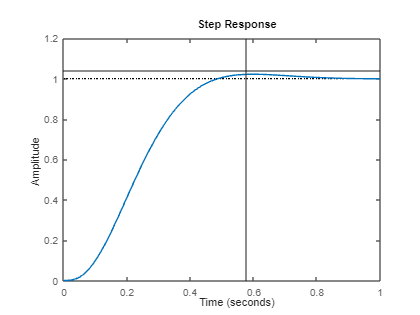

figure;step(g1mf);xline(Ts);yline(1.04);

Como pode ser observado na comparação das duas respostas, a primeira, com saturação, é um pouco mais lenta. No entanto, ela ainda está em conformidade com as definições de UP, Ts e erro em regime zero.

A resposta torna-se mais lenta devido à saturação do controle, limitado a um máximo de 25. Isso implica que levará mais tempo para que o controle tenha o mesmo efeito, em comparação com um sistema sem saturação, que poderia atingir valores mais elevados e interferir na resposta de maneira mais rápida, como pode ser observado abaixo. Isso contrasta com o controle sem saturação, que pode adotar qualquer valor e, portanto, modificar a resposta de forma mais rápida.

Devido à saturação, a escolha do polo deve ser feita com cuidado. Ele precisa ser mais rápido do que os polos complexos para não interferir no atendimento das especificações. No entanto, ele não pode ser muito rápido para evitar grandes oscilações no controle, oscilando entre o limite de saturação. É necessário encontrar um equilíbrio para evitar oscilações excessivas, seja por ser muito grande, próximo ao limite de saturação, ou muito pequeno, próximo ao limite inferior de saturação.

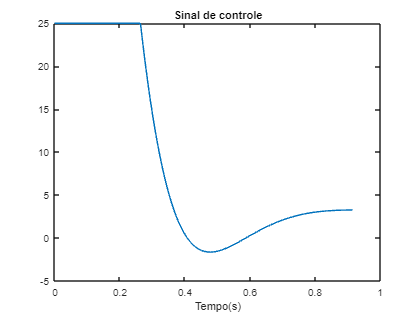

figure;plot(t,u);
title('Sinal de controle');
xlabel('Tempo(s)');

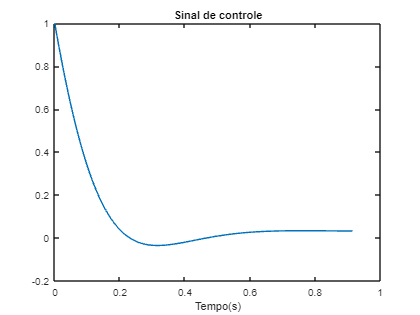

[y,t,x]=step(s1mf);
u=1-K*(x');
figure;plot(t,u);
title('Sinal de controle');
xlabel('Tempo(s)');

**Atividade 3) **Projetar uma realimentação integral de estados de forma que o erro para entrada degrau seja zero com a mesma especificação de UP e Ts do item 1. Neste caso, usa-se p1=1, pois a realimentação integral resolve o problema do erro em regime.

Faz parte da resposta:

- Plotar e interpretar a saída, o sinal de controle e os estados, mostrando o atendimento da especificação.

- Comentar o sinal de controle e seu valor em regime.

- Apresentar a FT de malha fechada e explicar por que o erro em regime para entrada degrau torna-se nulo.

**Resposta:**

O integrador (polo na origem) no sinal de erro assegura que a saída y tenda para a referência quando o sistema é estável, ou seja, quando todos os polos estão no SPE (Semi Plano Esquerdo). Dessa forma, temos um sistema do tipo 1, com a FT  $\frac{k_4}{s}C(sI-A+BK)^{-1}B$,  sendo $K=\left\lbrack \begin{array}{ccc}
k_1  & k_2  & k_3 
\end{array}\right\rbrack$.

Com base nos dados anteriores, o sistema aumentado será construído, incluindo um estado adicional devido ao polo na origem. Assim, o sistema resultante terá um total de 4 estados.

A1=[A [0;0;0];[-C 0]]

A1 =          0    1.0000         0         0
         0         0    1.0000         0
  -33.2500  -74.7500  -17.0000         0
  -11.0800         0         0         0


B1=[B;0];
Br=[0 ;0;0;1];
C1=[C 0];
D1=D;
sima=ss(A1,B1,C1,D1);

Ao modificar a localização de P4 e observar seu efeito na resposta y(t) = x1(t) e no sinal de controle u(t), é possível analisar como essa alteração afeta o comportamento do sistema. Portanto, é crucial garantir que P4, assim como P3, seja mais rápido do que os dois polos complexos que determinam o sistema atingindo as especificações. Isso contribuirá para a manutenção do desempenho desejado do sistema em relação às especificações estabelecidas.

p4 = -13;
polos4=[polos;p4];
K1=place(A1,B1,polos4);

**Sistema em malha fechada**

simf=ss(A1-B1*K1,Br,C1,D1)

simf =
 
  A = 
           x1      x2      x3      x4
   x1       0       1       0       0
   x2       0       0       1       0
   x3   -4576  -599.7  -38.89    1357
   x4  -11.08       0       0       0
 
  B = 
       u1
   x1   0
   x2   0
   x3   0
   x4   1
 
  C = 
          x1     x2     x3     x4
   y1  11.08      0      0      0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


O gráfico da resposta do sistema está mostrado abaixo, demonstrando que todas as especificações de UP, Ts e erro em regime zero foram atendidas. A adição de um polo na origem contribuiu para a conformidade do sistema com os requisitos estabelecidos.

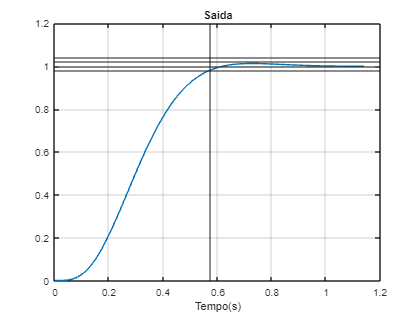

[y,t,x]=step(simf);
u=-K1*(x');
figure;plot(t,y);xline(Ts);yline(0.98);yline(1);yline(1.02);yline(1.04);grid;
title('Saida');xlabel('Tempo(s)');

O gráfico de estados abaixo ilustra as amplitudes de cada estado ao longo do tempo.

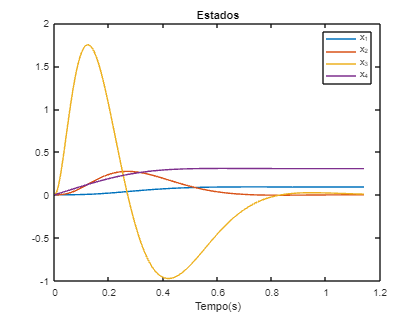

figure;
plot(t,x);legend('x_1','x_2','x_3','x_4');
title('Estados');xlabel('Tempo(s)');

O gráfico do sinal de controle é apresentado abaixo. Inicia em zero e aumenta gradualmente até atingir o pico. Nesse ponto, está aplicando uma quantidade significativa de controle para gerenciar o sistema. Posteriormente, o valor diminui, indicando que não é mais necessário aplicar tanta "força" de controle, até que o sinal se estabiliza constantemente em zero, sem a necessidade de mais intervenções intensas. Isso assegura a estabilidade da resposta do sistema, que, neste caso, apresenta erro zero em regime.

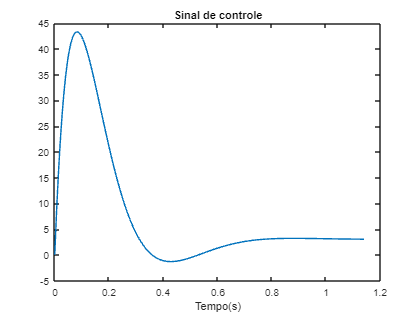

figure;
plot(t,u);
title('Sinal de controle');
xlabel('Tempo(s)');

**Atividade 4) **Nesta atividade usa-se o controlador anterior mas o sinal de controle está limitado pela saturação** sat.** Use a função [y,t,u] = simula_t6(s1a, KI,1,sat)  para simulação com a saturação e obter os valores de y,u,t, sendo que s1a é o sistema aumentado e KI é a realimentação integral de estados. Verifique se sob saturação a especificação é atendida. Caso não, altere a localização dos polos de malha fechada, lembrando que respostas mais rápidas exigem um sinal de controle de maior amplitude.

Faz parte da resposta:

- Plotar a saída sem e com saturação mostrando o atendimento da especificação

- Plotar e interpretar o sinal de controle sem e com saturação

- Explicar como foi feita a escolha dos polos de malha fechada tendo em vista a saturação.

s1 = sima

s1 =
 
  A = 
           x1      x2      x3      x4
   x1       0       1       0       0
   x2       0       0       1       0
   x3  -33.25  -74.75     -17       0
   x4  -11.08       0       0       0
 
  B = 
       u1
   x1   0
   x2   0
   x3   1
   x4   0
 
  C = 
          x1     x2     x3     x4
   y1  11.08      0      0      0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


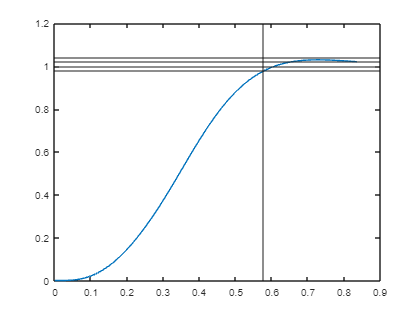

K = K1;
p1 = 1;
sat;
[y, t, u] = simula_t6(s1, K, p1, sat);
figure;plot(t,y);xline(Ts);yline(0.98);yline(1);yline(1.02);yline(1.04);

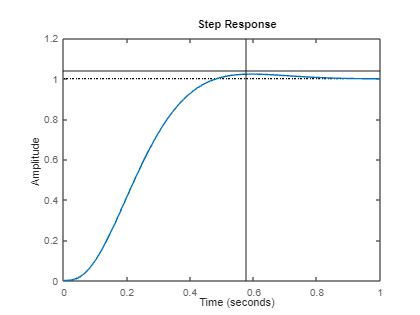

figure;step(g1mf);xline(Ts);yline(1.04);

Como pode ser observado ao comparar as duas respostas, a primeira, com saturação, é um pouco mais lenta, embora ainda esteja em conformidade com as definições de UP, Ts e erro em regime zero. A resposta torna-se mais lenta devido à saturação do controle, limitado a um máximo de 25.

Isso implica que levará mais tempo para que o controle tenha o mesmo efeito, comparado com um sistema sem saturação, que poderia atingir valores mais elevados e interferir na resposta de maneira mais rápida, como pode ser observado abaixo. Isso contrasta com o controle sem saturação, que pode adotar qualquer valor e, portanto, modificar a resposta de forma mais rápida.

Devido à saturação, a escolha do polo deve ser feita com cuidado. Ele precisa ser mais rápido do que os polos complexos para não interferir no atendimento das especificações. No entanto, ele não pode ser muito rápido para evitar grandes oscilações no controle, oscilando entre o limite de saturação. É necessário encontrar um equilíbrio para evitar oscilações excessivas, seja por ser muito grande, próximo ao limite de saturação, ou muito pequeno, próximo ao limite inferior de saturação.

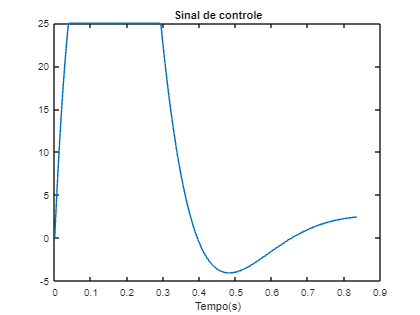

figure;plot(t,u);
title('Sinal de controle');
xlabel('Tempo(s)');

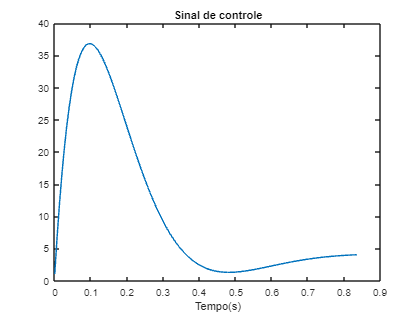

[y,t,x]=step(simf);
u=1-K*(x');
figure;plot(t,u);
title('Sinal de controle');
xlabel('Tempo(s)');